# Analysis in Frequency-Domain Computer Laboratory 2

## Example 1: Discrete-Time Fourier Transform - Implementation

(a) Implement the discrete-time Fourier transform [vX]=computeDTFT(vn,vx,vw) without using a loop. Consider the general form of the DTFT:

(b) Compute the DTFT for the given input signal x[n] = [1, 5, −1, 6, 3] using your function computeDTFT. Plot your result. Does the result agree with your expectations? Why or why not? 

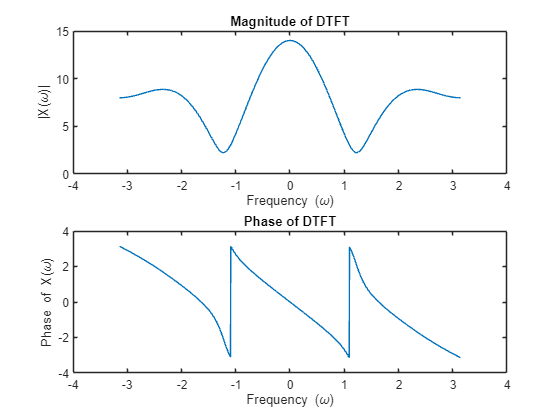

clc
clear
% Given input signal
xn = [1, 5, -1, 6, 3];

% Define the time indices
n = 0:length(xn)-1;

% Define the frequency range for plotting the DTFT
fftsize = 1000;
w = linspace(-pi, pi, fftsize);

% Compute the DTFT using the provided function
Xw_dtft = computeDTFT(n, xn, w);

% Plot the magnitude and phase of the DTFT
figure;

% Plot the magnitude
subplot(2, 1, 1);
plot(w, abs(Xw_dtft));
title('Magnitude of DTFT');
xlabel('Frequency (\omega)');
ylabel('|X(\omega)|');

% Plot the phase
subplot(2, 1, 2);
plot(w, angle(Xw_dtft));
title('Phase of DTFT');
xlabel('Frequency (\omega)');
ylabel('Phase of X(\omega)');

(c) Compare your function with the MATLAB command fft for the signal x[n]. Do the results agree? What are the restrictions on n and ωk? How can you modify the signals or the results so that both calculations agree? 

*first the signals dont match, it has to be shiftet *

% Compute FFT using MATLAB's fft function
Xw_fft = circshift(fft(xn,fftsize),fftsize/2)

Xw_fft =   -8.0000 + 0.0000i  -7.9997 + 0.0817i  -7.9988 + 0.1634i  -7.9973 + 0.2451i  -7.9953 + 0.3268i  -7.9926 + 0.4085i  -7.9893 + 0.4902i  -7.9855 + 0.5720i  -7.9810 + 0.6538i  -7.9759 + 0.7356i  -7.9702 + 0.8175i  -7.9639 + 0.8994i  -7.9570 + 0.9814i  -7.9495 + 1.0634i  -7.9413 + 1.1454i  -7.9325 + 1.2275i  -7.9231 + 1.3096i  -7.9130 + 1.3919i  -7.9023 + 1.4741i  -7.8909 + 1.5565i  -7.8789 + 1.6388i  -7.8662 + 1.7213i  -7.8528 + 1.8038i  -7.8387 + 1.8864i  -7.8240 + 1.9691i  -7.8085 + 2.0518i  -7.7923 + 2.1346i  -7.7754 + 2.2174i  -7.7578 + 2.3003i  -7.7394 + 2.3833i  -7.7203 + 2.4664i  -7.7004 + 2.5495i  -7.6797 + 2.6326i  -7.6583 + 2.7158i  -7.6361 + 2.7991i  -7.6131 + 2.8824i  -7.5892 + 2.9658i  -7.5646 + 3.0491i  -7.5391 + 3.1326i  -7.5127 + 3.2160i  -7.4856 + 3.2995i  -7.4575 + 3.3830i  -7.4285 + 3.4665i  -7.3987 + 3.5500i  -7.3680 + 3.6335i  -7.3363 + 3.7170i  -7.3038 + 3.8004i  -7.2702 + 3.8838i  -7.2358 + 3.9672i  -7.2004 + 4.0505i


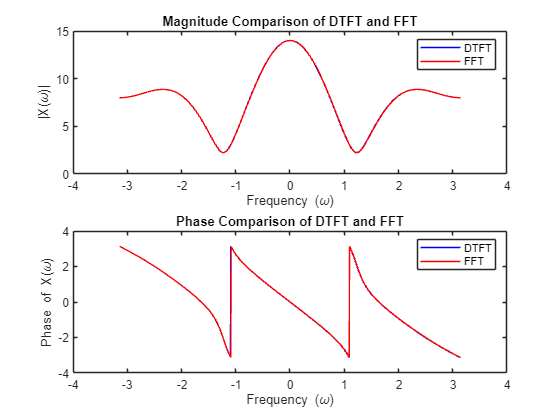


% Plot the magnitude comparison
figure;
subplot(2, 1, 1);
plot(w, abs(Xw_dtft), 'b');
hold on;
plot(w, abs(Xw_fft), 'r');
hold off;
title('Magnitude Comparison of DTFT and FFT');
xlabel('Frequency (\omega)');
ylabel('|X(\omega)|');
legend('DTFT','FFT');

% Plot the phase comparison
subplot(2, 1, 2);
plot(w, angle(Xw_dtft), 'b');
hold on;
plot(w, angle(Xw_fft), 'r');
hold off;
title('Phase Comparison of DTFT and FFT');
xlabel('Frequency (\omega)');
ylabel('Phase of X(\omega)');
legend('DTFT','FFT');
hold off;

You can use the command norm(vxX1-vx2,2) to calculate the Euclidean norm between the two results. 

*A higher FFT size is more acurate*

% Calculate Euclidean norm between the two results
norm_diff = norm(abs(Xw_dtft) - abs(Xw_fft), 2);
disp(['Euclidean norm between DTFT and FFT for FFT size ', num2str(fftsize), ': ', num2str(norm_diff)]);

Euclidean norm between DTFT and FFT for FFT size 1000: 0.81889


% Define the frequency range for plotting the DTFT
fftsize2 = 100;
w2 = linspace(-pi, pi, fftsize2);

% Compute the DTFT using the provided function
Xw_dtft2 = computeDTFT(n, xn, w2);
% Compute FFT using MATLAB's fft function
Xw_fft2 = circshift(fft(xn,fftsize2),fftsize2/2);
% Calculate Euclidean norm between the two results
norm_diff2 = norm(abs(Xw_dtft2) - abs(Xw_fft2), 2);
disp(['Euclidean norm between DTFT and FFT for FFT size ', num2str(fftsize2), ': ', num2str(norm_diff2)]);

Euclidean norm between DTFT and FFT for FFT size 100: 2.5933


## Example 2: Discrete-Time Fourier Transform - Properties

(a) 

• [H,w] = freqz(b, a, N) 

• [H,w] = freqz(b, a, N, ’whole’) 

• [H,w] = freqz(b, a, N, fs) 

What is the difference between those function calls? 

`[`[`h`](https://www.mathworks.com/help/releases/R2023b/signal/ref/freqz.html#bt8l4c4-h)`,`[`w`](https://www.mathworks.com/help/releases/R2023b/signal/ref/freqz.html#bt8l4c4-w)`] = freqz(`[`b`](https://www.mathworks.com/help/releases/R2023b/signal/ref/freqz.html?doclanguage=de&nocookie=true&prodfilter=ML%20SL%20EC%20OT%20ME%20CO%20SG%20SS%20RT&addons=arduinoio%20arduino&docviewer=helpbrowser&docrelease=R2023b&s_cid=pl_webdoc&loginurl=https%3A%2F%2F127.0.0.1%3A31515%2Ftoolbox%2Fmatlab%2Flogin%2Fweb%2Findex.html%3Fsnc%3DCPMILE%26external%3Dtrue%26channel%3D__mlfpmc__&searchsource=mw&snc=SBDOC5&container=jshelpbrowser#bt8l4c4_sep_shared-ba)`,`[`a`](https://www.mathworks.com/help/releases/R2023b/signal/ref/freqz.html?doclanguage=de&nocookie=true&prodfilter=ML%20SL%20EC%20OT%20ME%20CO%20SG%20SS%20RT&addons=arduinoio%20arduino&docviewer=helpbrowser&docrelease=R2023b&s_cid=pl_webdoc&loginurl=https%3A%2F%2F127.0.0.1%3A31515%2Ftoolbox%2Fmatlab%2Flogin%2Fweb%2Findex.html%3Fsnc%3DCPMILE%26external%3Dtrue%26channel%3D__mlfpmc__&searchsource=mw&snc=SBDOC5&container=jshelpbrowser#bt8l4c4_sep_shared-ba)`,`[`n`](https://www.mathworks.com/help/releases/R2023b/signal/ref/freqz.html?doclanguage=de&nocookie=true&prodfilter=ML%20SL%20EC%20OT%20ME%20CO%20SG%20SS%20RT&addons=arduinoio%20arduino&docviewer=helpbrowser&docrelease=R2023b&s_cid=pl_webdoc&loginurl=https%3A%2F%2F127.0.0.1%3A31515%2Ftoolbox%2Fmatlab%2Flogin%2Fweb%2Findex.html%3Fsnc%3DCPMILE%26external%3Dtrue%26channel%3D__mlfpmc__&searchsource=mw&snc=SBDOC5&container=jshelpbrowser#bt8l4c4_sep_shared-n)`)`* returns the *`n`*-point frequency response vector *`h`* and the corresponding angular frequency vector *`w`* for the digital filter with transfer function coefficients stored in *`b`* and *`a`*.*

`[`[`h`](https://www.mathworks.com/help/releases/R2023b/signal/ref/freqz.html#bt8l4c4-h)`,`[`w`](https://www.mathworks.com/help/releases/R2023b/signal/ref/freqz.html#bt8l4c4-w)`] = freqz(``___``,`[`n`](https://www.mathworks.com/help/releases/R2023b/signal/ref/freqz.html?doclanguage=de&nocookie=true&prodfilter=ML%20SL%20EC%20OT%20ME%20CO%20SG%20SS%20RT&addons=arduinoio%20arduino&docviewer=helpbrowser&docrelease=R2023b&s_cid=pl_webdoc&loginurl=https%3A%2F%2F127.0.0.1%3A31515%2Ftoolbox%2Fmatlab%2Flogin%2Fweb%2Findex.html%3Fsnc%3DCPMILE%26external%3Dtrue%26channel%3D__mlfpmc__&searchsource=mw&snc=SBDOC5&container=jshelpbrowser#bt8l4c4_sep_shared-n)`,'whole')`* returns the frequency response at *`n`* sample points around the entire unit circle.*

`[`[`h`](https://www.mathworks.com/help/releases/R2023b/signal/ref/freqz.html#bt8l4c4-h)`,`[`f`](https://www.mathworks.com/help/releases/R2023b/signal/ref/freqz.html#bt8l4c4-f)`] = freqz(``___``,`[`n`](https://www.mathworks.com/help/releases/R2023b/signal/ref/freqz.html?doclanguage=de&nocookie=true&prodfilter=ML%20SL%20EC%20OT%20ME%20CO%20SG%20SS%20RT&addons=arduinoio%20arduino&docviewer=helpbrowser&docrelease=R2023b&s_cid=pl_webdoc&loginurl=https%3A%2F%2F127.0.0.1%3A31515%2Ftoolbox%2Fmatlab%2Flogin%2Fweb%2Findex.html%3Fsnc%3DCPMILE%26external%3Dtrue%26channel%3D__mlfpmc__&searchsource=mw&snc=SBDOC5&container=jshelpbrowser#bt8l4c4_sep_shared-n)`,`[`fs`](https://www.mathworks.com/help/releases/R2023b/signal/ref/freqz.html?doclanguage=de&nocookie=true&prodfilter=ML%20SL%20EC%20OT%20ME%20CO%20SG%20SS%20RT&addons=arduinoio%20arduino&docviewer=helpbrowser&docrelease=R2023b&s_cid=pl_webdoc&loginurl=https%3A%2F%2F127.0.0.1%3A31515%2Ftoolbox%2Fmatlab%2Flogin%2Fweb%2Findex.html%3Fsnc%3DCPMILE%26external%3Dtrue%26channel%3D__mlfpmc__&searchsource=mw&snc=SBDOC5&container=jshelpbrowser#bt8l4c4_sep_shared-fs)`)`* returns the frequency response vector *`h`* and the corresponding physical frequency vector *`f`* for a digital filter designed to filter signals sampled at a rate *`fs`*.*

(b) Download all four animal sounds from the Moodle course site. Use the built-in MATLAB function audioread() to load the soundfiles into the workspace properly.

dog=audioread('sound\sound\bark_dog.wav');
fox=audioread('sound\sound\bark_fox.wav');
cat=audioread('sound\sound\meow_cat.wav');
duck=audioread('sound\sound\quaki_duck.wav');

(c) Plot the time signal and the DTFT of each one. Please title your plots and label your axes. For each DTFT, choose N greater than the length of the signal in order to get a smooth plot. Comment on what you see in the DTFT’s.

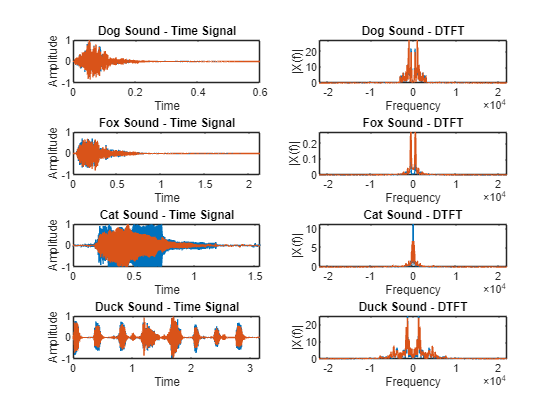

% Plot time signal and DTFT for each animal sound without using freqz
fs = 44100;  % Assuming a common sampling rate for the sounds
% Define a function for computing DTFT
computeDTFT = @(x, N) fftshift(fft(x, N));

figure;

% Dog sound
subplot(4, 2, 1);
t_dog = (0:length(dog)-1)/fs;
plot(t_dog, dog);
title('Dog Sound - Time Signal');
xlabel('Time');
ylabel('Amplitude');

subplot(4, 2, 2);
N = 1000;
f_dog = linspace(-fs/2, fs/2, N);
X_dog = computeDTFT(dog, N);
plot(f_dog, abs(X_dog));
title('Dog Sound - DTFT');
xlabel('Frequency');
ylabel('|X(f)|');

% Fox sound
subplot(4, 2, 3);
t_fox = (0:length(fox)-1)/fs;
plot(t_fox, fox);
title('Fox Sound - Time Signal');
xlabel('Time');
ylabel('Amplitude');

subplot(4, 2, 4);
N = 1000;
f_fox = linspace(-fs/2, fs/2, N);
X_fox = computeDTFT(fox, N);
plot(f_fox, abs(X_fox));
title('Fox Sound - DTFT');
xlabel('Frequency');
ylabel('|X(f)|');

% Cat sound
subplot(4, 2, 5);
t_cat = (0:length(cat)-1)/fs;
plot(t_cat, cat);
title('Cat Sound - Time Signal');
xlabel('Time');
ylabel('Amplitude');

subplot(4, 2, 6);
N = 1000;
f_cat = linspace(-fs/2, fs/2, N);
X_cat = computeDTFT(cat, N);
plot(f_cat, abs(X_cat));
title('Cat Sound - DTFT');
xlabel('Frequency');
ylabel('|X(f)|');

% Duck sound
subplot(4, 2, 7);
t_duck = (0:length(duck)-1)/fs;
plot(t_duck, duck);
title('Duck Sound - Time Signal');
xlabel('Time');
ylabel('Amplitude');

subplot(4, 2, 8);
N = 1000;
f_duck = linspace(-fs/2, fs/2, N);
X_duck = computeDTFT(duck, N);
plot(f_duck, abs(X_duck));
title('Duck Sound - DTFT');
xlabel('Frequency');
ylabel('|X(f)|');

(d) So far you have plotted with the frequency axis in radians, which may be hard to interpret. If you know the sampling rate of the data, however, you can “un-normalize” the frequency axis while keeping the same plot shape. To do this job, we can use freqz with different parameters: 

[x, Fs, b] = wavread( ‘cat.wav’ ); 

[H, F] = freqz( x, 1, length(x), Fs ); 

What is the frequency of the first peak (fundamental frequency) of each animal sound?

% Load the animal sound
[x_cat, Fs_cat] = audioread('sound\sound\meow_cat.wav');
[x_dog, Fs_dog] = audioread('sound\sound\bark_dog.wav');
[x_fox, Fs_fox] = audioread('sound\sound\bark_fox.wav');
[x_duck, Fs_duck] = audioread('sound\sound\quaki_duck.wav');

% Compute the frequency response using freqz for each sound
[H_cat, F_cat] = freqz(x_cat(:, 1), 1, length(x_cat), Fs_cat);
[H_dog, F_dog] = freqz(x_dog(:, 1), 1, length(x_dog), Fs_dog);
[H_fox, F_fox] = freqz(x_fox(:, 1), 1, length(x_fox), Fs_fox);
[H_duck, F_duck] = freqz(x_duck(:, 1), 1, length(x_duck), Fs_duck);

% Find the fundamental frequency for each sound
[~, index_cat] = max(abs(H_cat));
fundamental_frequency_cat = F_cat(index_cat);

[~, index_dog] = max(abs(H_dog));
fundamental_frequency_dog = F_dog(index_dog);

[~, index_fox] = max(abs(H_fox));
fundamental_frequency_fox = F_fox(index_fox);

[~, index_duck] = max(abs(H_duck));
fundamental_frequency_duck = F_duck(index_duck);

% Display fundamental frequencies
disp(['Fundamental frequency of the cat sound: ', num2str(fundamental_frequency_cat), ' Hz']);

Fundamental frequency of the cat sound: 1186.4585 Hz


disp(['Fundamental frequency of the dog sound: ', num2str(fundamental_frequency_dog), ' Hz']);

Fundamental frequency of the dog sound: 464.3246 Hz


disp(['Fundamental frequency of the fox sound: ', num2str(fundamental_frequency_fox), ' Hz']);

Fundamental frequency of the fox sound: 1618.7817 Hz


disp(['Fundamental frequency of the duck sound: ', num2str(fundamental_frequency_duck), ' Hz']);

Fundamental frequency of the duck sound: 1381.6931 Hz


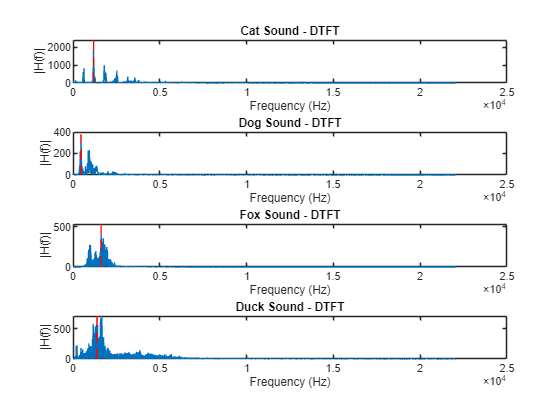


% Plot the DTFTs
figure;
subplot(4, 1, 1);
plot(F_cat, abs(H_cat));
hold on;
plot([fundamental_frequency_cat, fundamental_frequency_cat], [0, max(abs(H_cat))], 'r--');
hold off;
title('Cat Sound - DTFT');
xlabel('Frequency (Hz)');
ylabel('|H(f)|');

subplot(4, 1, 2);
plot(F_dog, abs(H_dog));
hold on;
plot([fundamental_frequency_dog, fundamental_frequency_dog], [0, max(abs(H_dog))], 'r--');
hold off;
title('Dog Sound - DTFT');
xlabel('Frequency (Hz)');
ylabel('|H(f)|');

subplot(4, 1, 3);
plot(F_fox, abs(H_fox));
hold on;
plot([fundamental_frequency_fox, fundamental_frequency_fox], [0, max(abs(H_fox))], 'r--');
hold off;
title('Fox Sound - DTFT');
xlabel('Frequency (Hz)');
ylabel('|H(f)|');

subplot(4, 1, 4);
plot(F_duck, abs(H_duck));
hold on;
plot([fundamental_frequency_duck, fundamental_frequency_duck], [0, max(abs(H_duck))], 'r--');
hold off;
title('Duck Sound - DTFT');
xlabel('Frequency (Hz)');
ylabel('|H(f)|');

## Example 3: Simple Three-Band Equalizer

(a) The music music.wav file is standard CD quality, sampled at 44.1 KHz with a 16-bit word size for each channel. For your report, answer the following: If the file is 10 seconds long, then how many samples of data will there be? (Hint: the data samples are in stereo.) If we needed to transmit at this CD quality, with no compression, how many bits/second would be needed?

% Given values
duration = 10;  % seconds
samplingRate = 44100;  % Hz
numChannels = 2;

% Calculate total number of samples
totalSamples = duration * samplingRate * numChannels;
disp(['Total Samples: ', num2str(totalSamples)]);

Total Samples: 882000


% Given values
bitDepth = 16;  % bits
bitsPerSecond = samplingRate;

% Calculate data rate
dataRate =   bitDepth * numChannels * bitsPerSecond;
disp(['Data Rate (Bits/Second): ', num2str(dataRate)]);

Data Rate (Bits/Second): 1411200


% Convert data rate to megabits per second
dataRateMbps = dataRate / 1e6;
disp(['Data Rate (Mbps): ', num2str(dataRateMbps)]);

Data Rate (Mbps): 1.4112


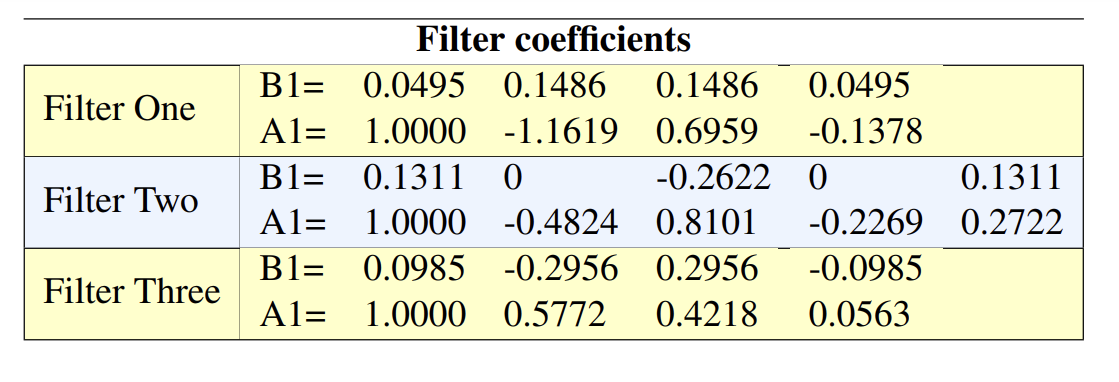

(b) We have three filters, each defined by the difference-equation coefficients in the filter coefficients table. What are the properties of each filter? You will learn how to design them later. For this moment, just investigate which one is LP, HP, BP. Use freqz with F s = 44100 and plot the frequency response of each filter and the pole-diagram using zplane. 

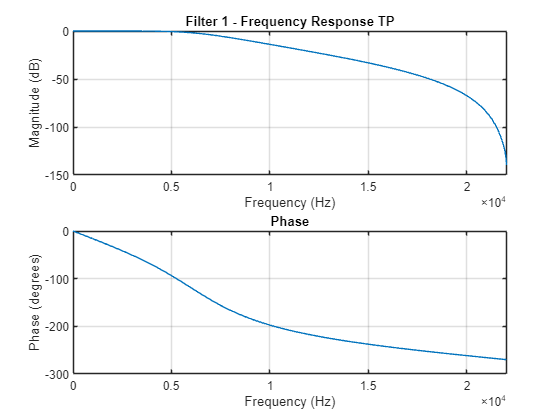

clear all; clc; close all;
% Filter coefficients (Replace with actual coefficients)
b_1 = [0.0495, 0.1486, 0.1486 , 0.0495];  % filter one
a_1 = [1.000, -1.1619, 0.6959, -0.1378];

b_2 = [0.1311, 0, -0.2622, 0, 0.1311];  % fiter two
a_2 = [1.000, -0.4824, 0.8101, -0.2269, 0.2722];

b_3 = [0.0985, -0.2956, 0.2956, -0.0985];  % Filter three
a_3 = [1.000, 0.5772, 0.4218, 0.0563];

% Sampling rate
Fs = 44100;
fftsize = 1000;
% Plot the frequency response and pole-diagram for each filter
figure;
freqz(b_1, a_1, fftsize, Fs);
title('Filter 1 - Frequency Response TP');

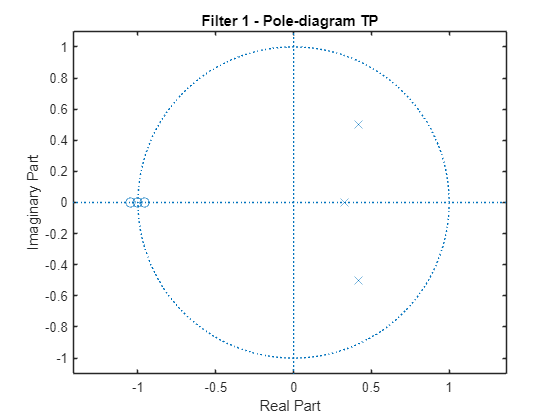

figure;
zplane(b_1, a_1);
title('Filter 1 - Pole-diagram TP');

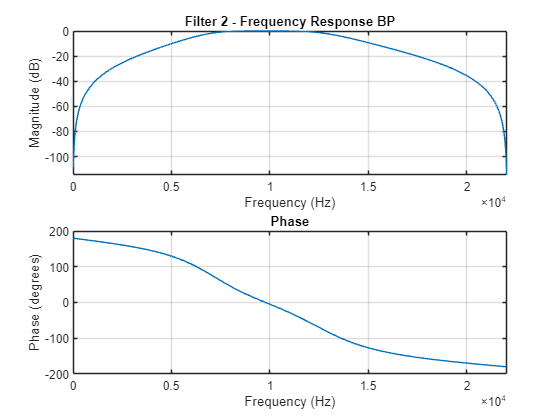

figure;
freqz(b_2, a_2, fftsize, Fs);
title('Filter 2 - Frequency Response BP');

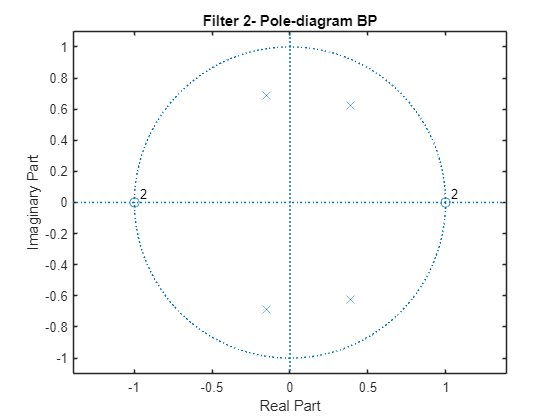

figure;
zplane(b_2, a_2);
title('Filter 2- Pole-diagram BP');

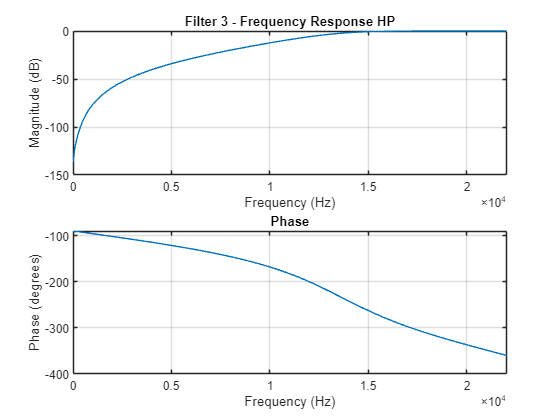

figure;
freqz(b_3, a_3, fftsize, Fs);
title('Filter 3 - Frequency Response HP');

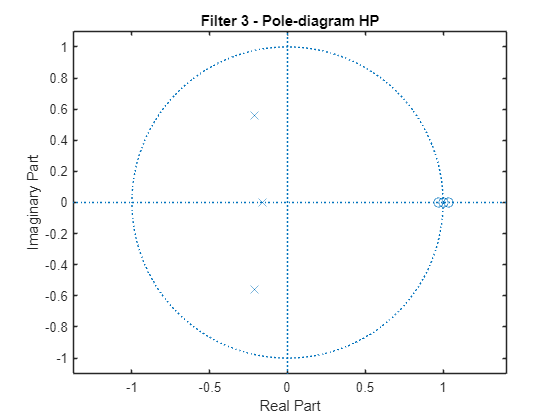

figure;
zplane(b_3, a_3);
title('Filter 3 - Pole-diagram HP');

(c) The idea of an equalizer is to filter, weight, and sum. Audio mixing boards do this, though with many more than the three channels we have here. Use the MATLAB code below to finish your own equalizer script. Try different values for G1, G2, and G3 (shown in the block diagram) and listen to the resulting y[n].

% load music
[x, Fs] = audioread ('music\chipi.mp3'); %Examplified function call
x_left = x(:,1);
x_right = x(:,2);
% filter 1
y1_left = filter(b_1, a_1, x_left);
y1_right = filter(b_1, a_1, x_right) ;
y1 = [y1_left y1_right];
% filter 2
y2_left = filter(b_2, a_2, x_left);
y2_right = filter(b_2, a_2, x_right) ;
y2 = [y2_left y2_right];
%filter 3
y3_left = filter(b_3, a_3, x_left);
y3_right = filter(b_3, a_3, x_right) ;
y3 = [y3_left y3_right];
% at the end, we need to sum
G1 = 1.1;
G2 = 0.5;
G3 = 2;
y = G1*y1 + G2*y2 + G3*y3;
sound (y, Fs)

(d) Compare the filtered audio with the original signal. What does each filter do to the music? Why don’t you hear y1, y2, y3 independently as distinct sources? 

*You don't hear *`y1`*, *`y2`*, and *`y3`* independently as distinct sources, because the signals are combined linearly with different gains*

clear sound

## Example 4: Fast Fourier Transformation - Reverse Engineering

(a) Investigate the radix_fft_dit.m script. Identify and note the purpose of key sections: zeropadding, bit-reversal, and FFT computation loop. 

*Zero Padding*

*This section performs zero-padding on the input signal *`x`* to make its length a power of 2. The *`nextpow2`* function is used to find the next power of 2 greater than or equal to the length of the input signal. The signal is then padded with zeros to reach this length.*

*Bit-Reversal*

*This section performs bit-reversal on the zero-padded signal. Bit-reversal is a crucial step in the FFT algorithm to ensure that the input sequence is in the correct order for the subsequent FFT computation.*

*FFT Computation Loop*

*This section implements the main FFT computation loop using the Radix-2 DIT algorithm. It iterates through different stages of the FFT, each stage doubling the size of the butterfly operations. The loop performs complex multiplication using twiddle factors *`w`* and updates the values of the input sequence *`x`* in-place.*

(b) Analyze the run_fft.m script. Understand how it generates a test signal and how the radix_fft_dit function is applied. 

* A test signal is generated by summing sine waves with frequencies specified in the *`frequ`* vector. *

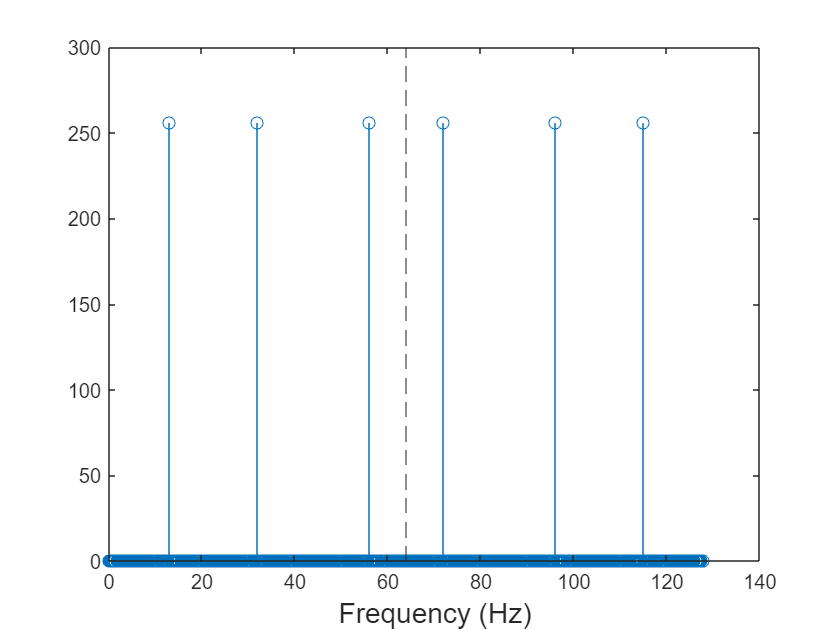

run_fft

(c) Make a minor change in the radix_fft_dit.m script (e.g., alter a loop). Observe and document the effects on the FFT output when run_fft.m is executed.

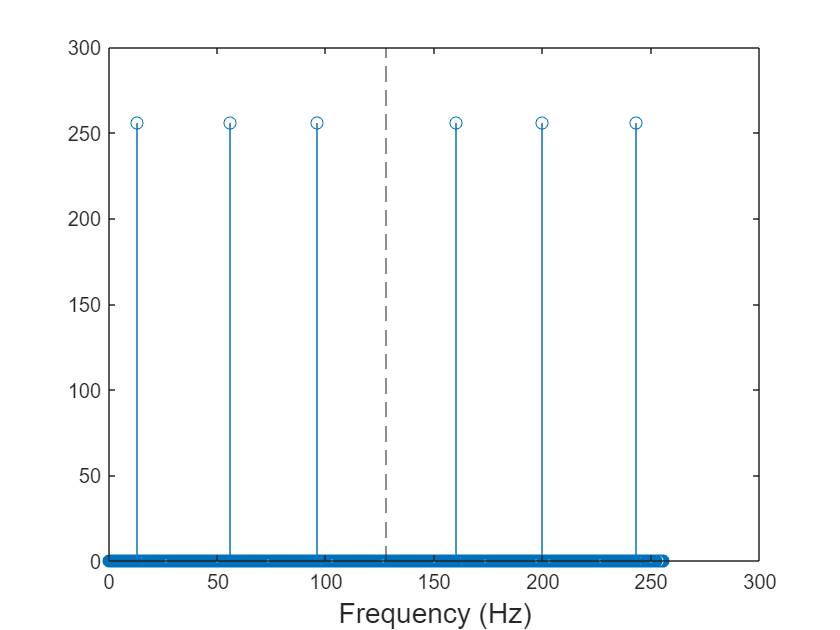

mod_run_fft

*In the original run function, the signal is mirrored around half of the sampling rate (Fs/2). Since the sampling rate (Fs) must be at least twice the highest frequency to avoid aliasing, this mirroring occurs at Fs/2. When using a larger Fs, such as 256, this mirroring effect no longer occurs.*

(d) Test signal parameters (frequency, amplitude) in run fft.m, does aliasing occur? Analyze how these changes affect the FFT output.

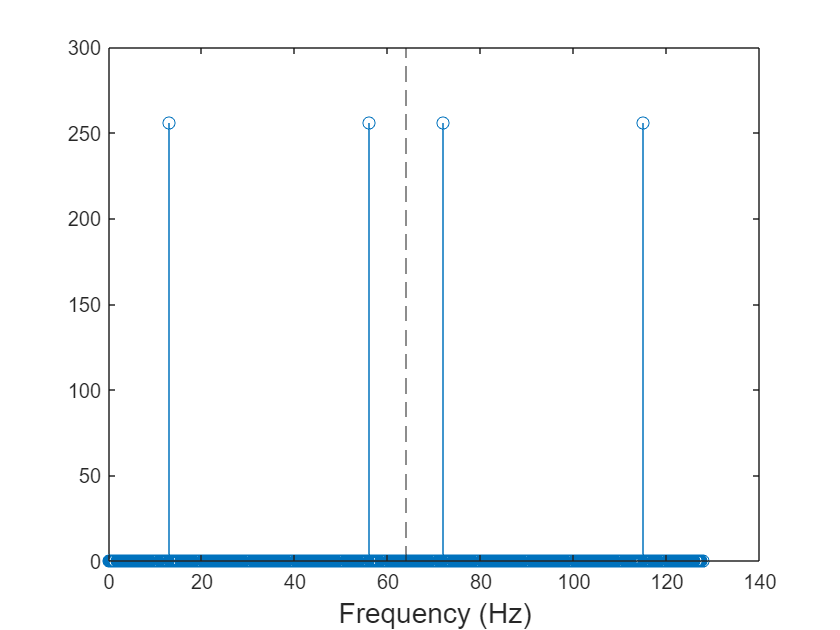

mod2_run_fft

*Values disappear directly at Fs/2.*

## Example 5: The MATLAB FFT, what is the circular convolution?

clc
clear

(a) Generate a signal x[n] with the sampling frequency fs = 200Hz and a sample length of N = 512 samples. The signal should include the following frequencies f = [13, 56, 60]Hz. Use the function fft() to compute the DFT of the signal. Create a proper frequency vector in order to plot a proper frequency spectrum. What do you observe?

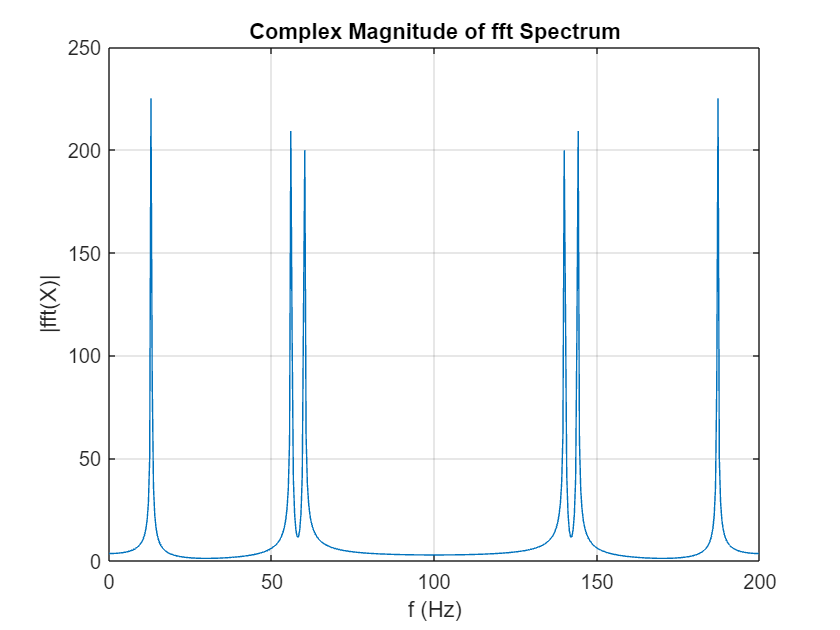

fs = 200;
N = 512;
f = [13, 56, 60];
index = 0:1:N-1; 
T = 1/fs;             % Sampling period 
t = index.*T;        % Time vector
X = sum(sin(2*pi*f'*t),1);
Y = fft(X);
figure;
plot(fs/N*(0:N-1),abs(Y))
title("Complex Magnitude of fft Spectrum")
xlabel("f (Hz)")
ylabel("|fft(X)|")

grid on

*Peaks at 13 Hz, 56 Hz, and 60 Hz:*

- *You see peaks in the frequency spectrum at 13 Hz, 56 Hz, and 60 Hz, corresponding to the frequencies you included in the signal.*

*Magnitude of Peaks:*

- *The magnitude of each peak indicates the amplitude or strength of the corresponding frequency component. Higher magnitudes imply stronger contributions from those frequencies in the signal.*

*Aliasing:*

- *The sampling frequency (200 Hz) is sufficiently to  capture the frequencies in the signal. Otherwise aliasing occurs when the Nyquist criterion is not satisfied.*

(b) Now change the underlying frequencies within the signal to f = [13, 56, 120]Hz. What could be observed now? What is actually happening? 

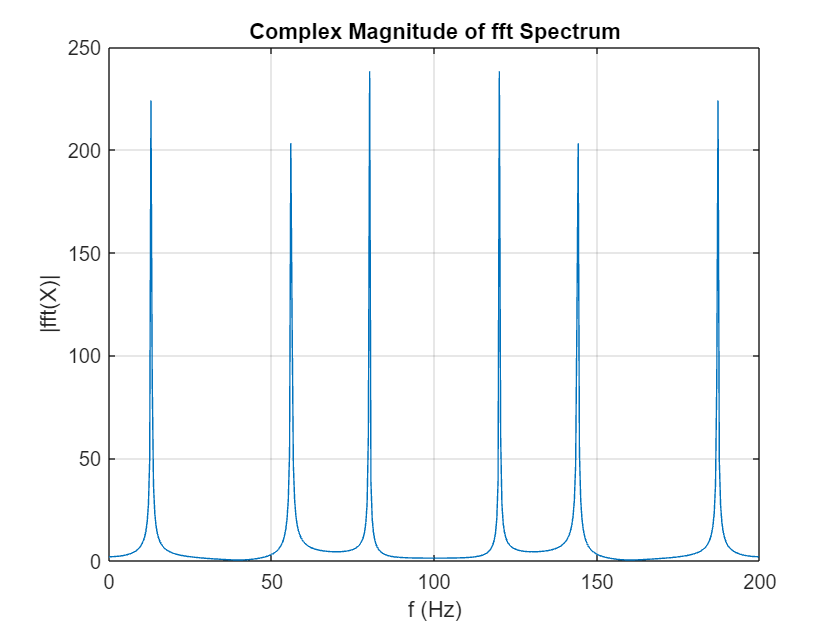

clc
clear
fs = 200;
N = 512;
f = [13, 56, 120];
index = 0:1:N-1; 
T = 1/fs;             % Sampling period 
t = index.*T;        % Time vector
X = sum(sin(2*pi*f'*t),1);
Y = fft(X);
figure;
plot(fs/N*(0:N-1),abs(Y))
title("Complex Magnitude of fft Spectrum")
xlabel("f (Hz)")
ylabel("|fft(X)|")

grid on

*New peaks in the frequency spectrum at 120 Hz and at 80Hz.*

*Aliasing occurs. The new frequency (120 Hz) is more than half of the sampling frequency, aliasing effects manifest in the frequency spectrum.*

(c) Calculate the (as last time) linear convolution of the two given signals x1[n] and x2[n] and plot the result. Two signals are given by 

x1[n] = 1δ[n] − 1δ[n − 1] + 3δ[n − 2] 

and 

x2[n] = 2δ[n] − 1δ[n − 1] + 1δ[n − 2]. 

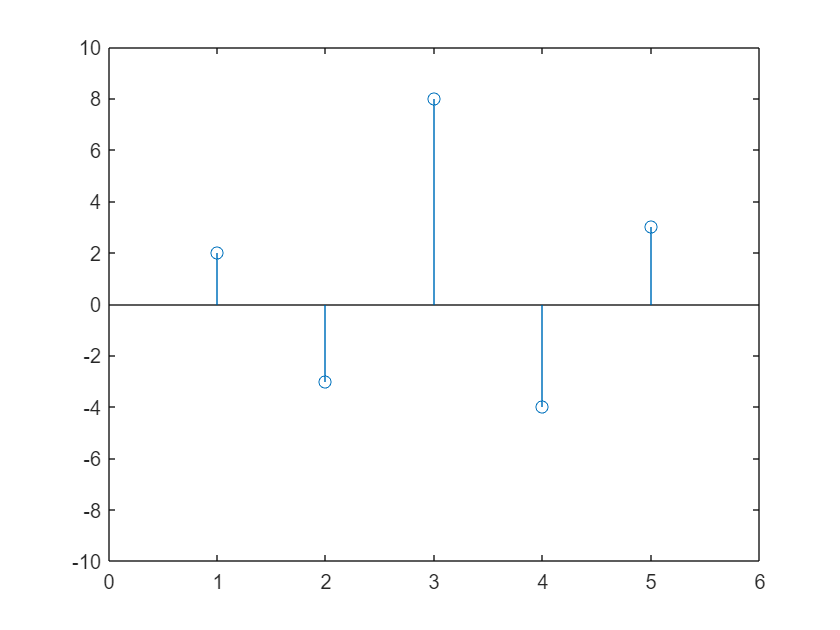

clc
clear
x1 = [1,-1,3];
x2 = [2,-1,1];

convx = conv(x1,x2);
figure;
stem(convx)

xlim([0 6])
ylim([-10 10])

(d) Calculate the DFT (MATLAB FFT) of both signals, multiply the DFT coefficients, and calculate the inverse of the result. Why is the result different from (c)? 

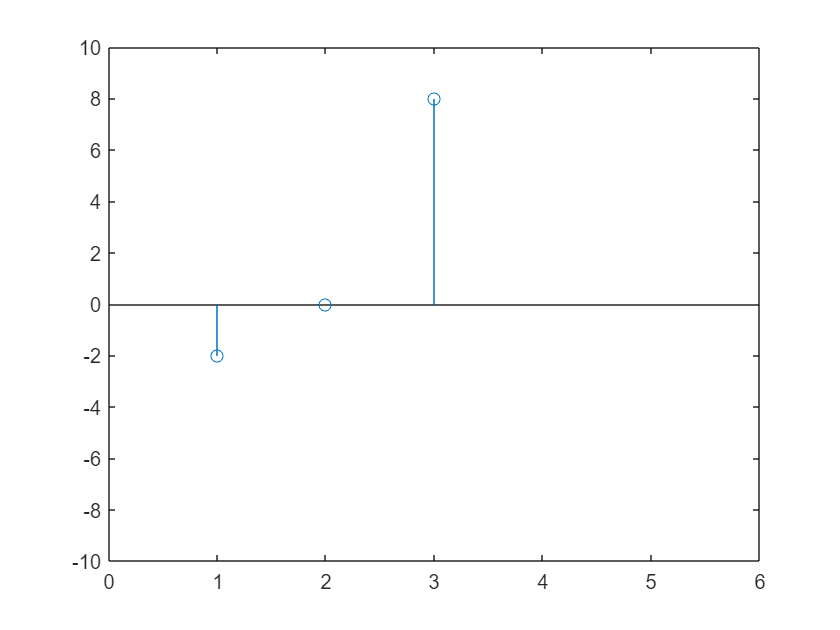

fft_x1 = fft(x1);
fft_x2 = fft(x2);
fft_X= fft_x1.*fft_x2;
ifft_X=ifft(fft_X);
stem(ifft_X)
xlim([0 6])
ylim([-10 10])

(e) Concatenate 2 zeros to the given signals and repeat (c) again. Why does the results now agree with (d)?

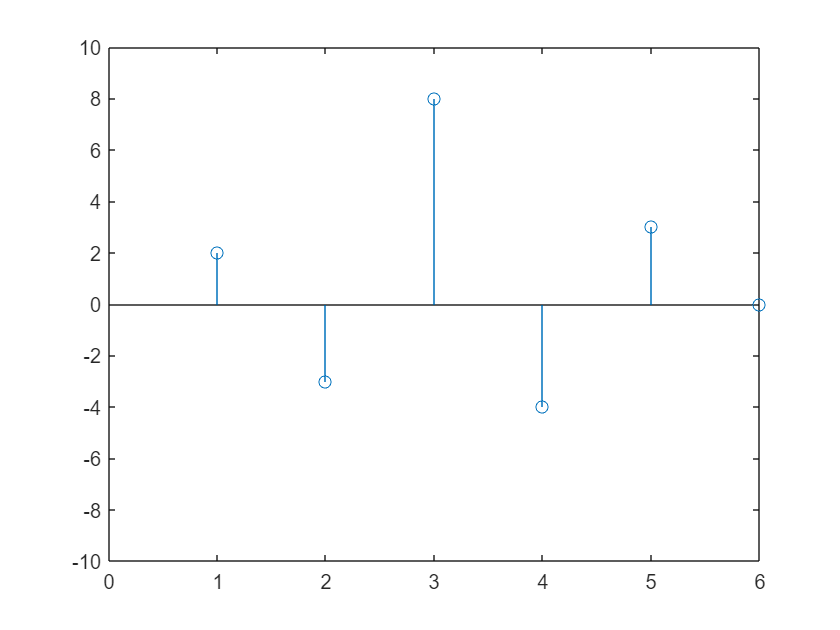

clc
clear
x1 = [1,-1,3,0,0];
x2 = [2,-1,1,0,0];

convx = conv(x1,x2);
figure;
stem(convx)

xlim([0 6])
ylim([-10 10])

fft_x1 = fft(x1);
fft_x2 = fft(x2);
fft_X= fft_x1.*fft_x2;
ifft_X=ifft(fft_X);
stem(ifft_X)
xlim([0 6])
ylim([-10 10])

*Difference Between Linear and Circular Convolution:*

*The result obtained from circular convolution (frequency domain multiplication and inverse DFT) is different from linear convolution. This is because circular convolution assumes periodic extension of the signals, and it is equivalent to circular (or cyclic) convolution in the time domain. In contrast, linear convolution considers zero-padding and extends the signals infinitely in both directions.*

## Example 6: Feature Extraction - Speech recognition

Investigate in the MATLAB functions audioread, fft, histogram using the MATLAB help In order to illustrate the use of the FFT, we investigate in a small speech recognition algorithm. The main goal is not to teach speech recognition techniques, but to show that the spectrum of a signal provides us useful information of a signal. Our file set contains of 40 ’yes’ and ’no’ files, where male and female speaker utter the phrase. (F s = 16000) The main goal is to implement a function yes no.m that distinguishes between an uttered ’yes’ and ’no’.

(a) Compute the power spectrum of a signal using the fft compare an uttered ’yes’ and ’no’ example. What do you notice comparing these two spectra? In order to realize this we could create use the second equation which also is related to parsevals theorem: 

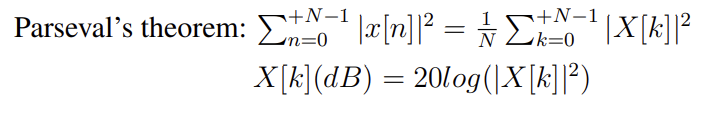

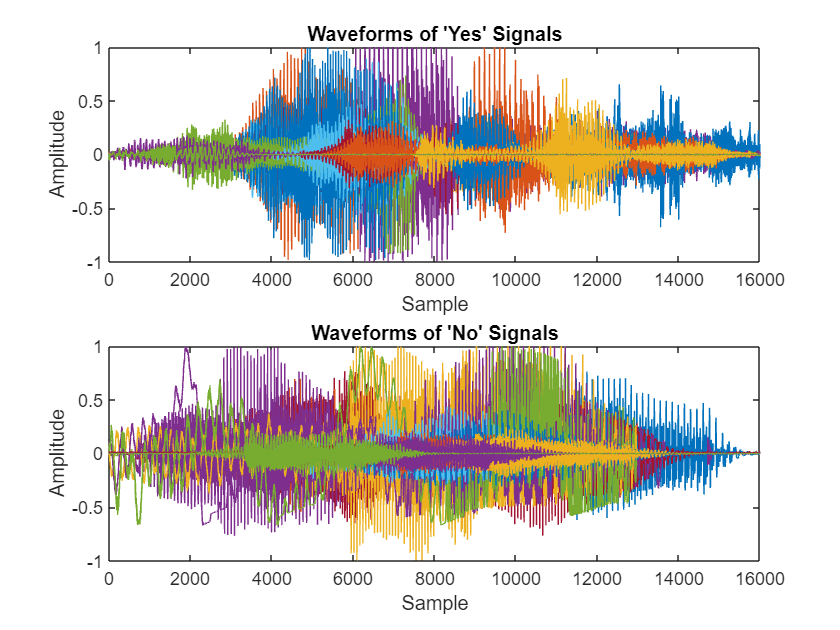


adsYES = audioDatastore('Speech soundfiles\yes\');
allYesSignals = readall(adsYES); % this reads all the audio files in one shot
adsNO = audioDatastore('Speech soundfiles\no\');
allnoSignals = readall(adsNO); % this reads all the audio files in one shot
[~,fs]=audioread("Speech soundfiles\yes\0a7c2a8d_nohash_0.wav");
% Plotting all waveforms in the same figure
figure;

% Plotting 'Yes' signals
subplot(2,1,1)
for i = 1:length(allYesSignals)
    plot(allYesSignals{i});
    title('Waveforms of ''Yes'' Signals');
    xlabel('Sample');
    ylabel('Amplitude');
    hold on;
end
hold off;

% Plotting 'No' signals
subplot(2,1,2)
for i = 1:length(allnoSignals)
    plot(allnoSignals{i});
    title('Waveforms of ''No'' Signals');
    xlabel('Sample');
    ylabel('Amplitude');
    hold on;
end
hold off;

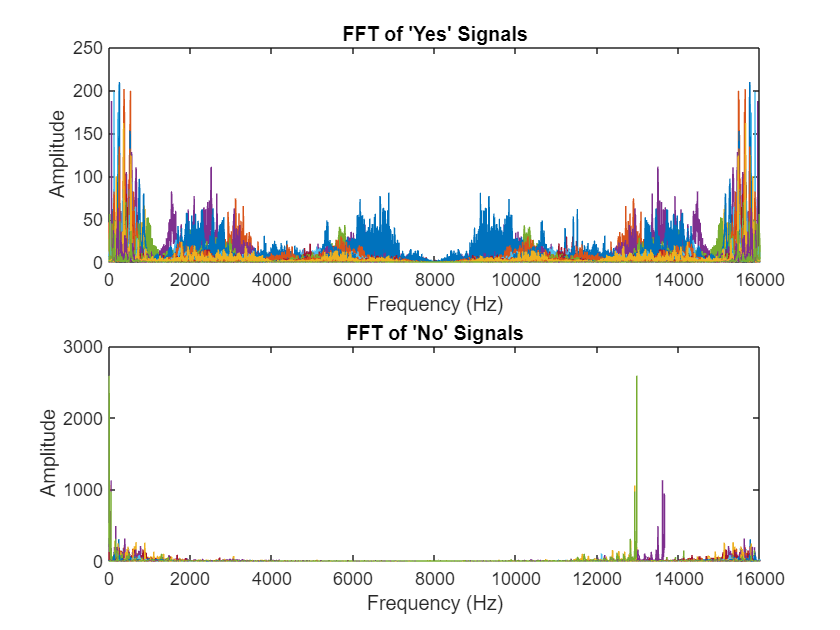


% Plotting all waveforms in the same figure
figure;

% Plotting 'Yes' signals
subplot(2,1,1)
for i = 1:length(allYesSignals)
    plot(abs(fft(allYesSignals{i})));
    title('FFT of ''Yes'' Signals');
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    hold on;
end
hold off;

% Plotting 'No' signals
subplot(2,1,2)
for i = 1:length(allnoSignals)
    plot(abs(fft(allnoSignals{i})));
    title('FFT of ''No'' Signals');
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    hold on;
end
hold off;

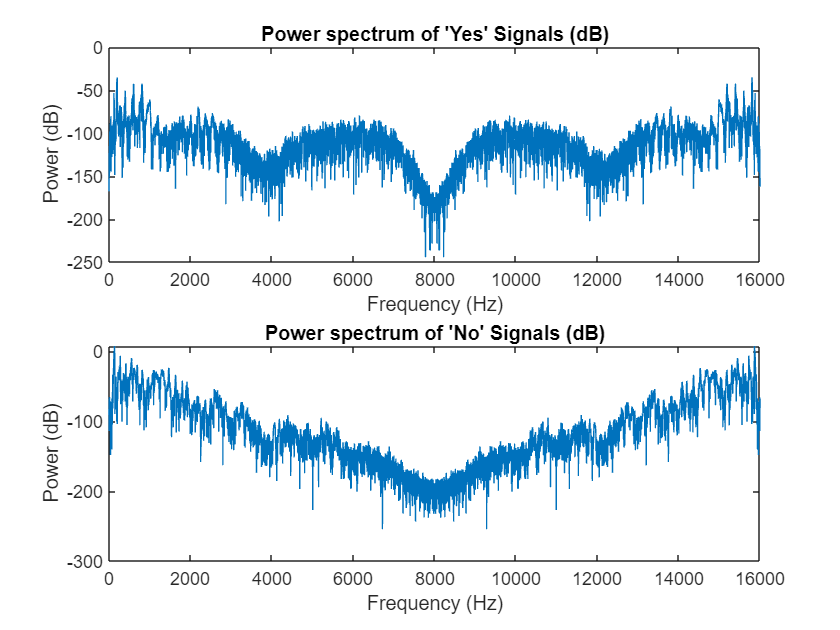

% Plotting all waveforms in the same figure
figure;

% Plotting 'Yes' signals
subplot(2,1,1)
for i = 1
    %1:length(allYesSignals)
    signal_yes_fft = fft(allYesSignals{i});
    power_spectrum_yes = abs(signal_yes_fft).^2 / length(allYesSignals{i});
    power_spectrum_yes_dB = 20 * log10(power_spectrum_yes); % Convert to dB

    plot(power_spectrum_yes_dB);
    title('Power spectrum of ''Yes'' Signals (dB)');
    xlabel('Frequency (Hz)');
    ylabel('Power (dB)');
    hold on;
end
hold off;

% Plotting 'No' signals
subplot(2,1,2)
for i = 4
%1:length(allnoSignals)
    signal_no_fft = fft(allnoSignals{i});
    power_spectrum_no = abs(signal_no_fft).^2 / length(allnoSignals{i});
    power_spectrum_no_dB = 20 * log10(power_spectrum_no); % Convert to dB

    plot(power_spectrum_no_dB);
    title('Power spectrum of ''No'' Signals (dB)');
    xlabel('Frequency (Hz)');
    ylabel('Power (dB)');
    hold on;
end
hold off;

(b) What could be a possible feature in order to differentiate between these sets. One possible feature would be to take the sum of the magnitude of the FFT components that correspond to the frequencies of NO interest and divide it by the sum of the magnitude of the FFT components that corresponds to the frequency band of interest. (HINT: We could pick these proper regions by identifying a suitable range on the x-Axis) Write a function that calculates the ratio between the FONI and the FOI. 

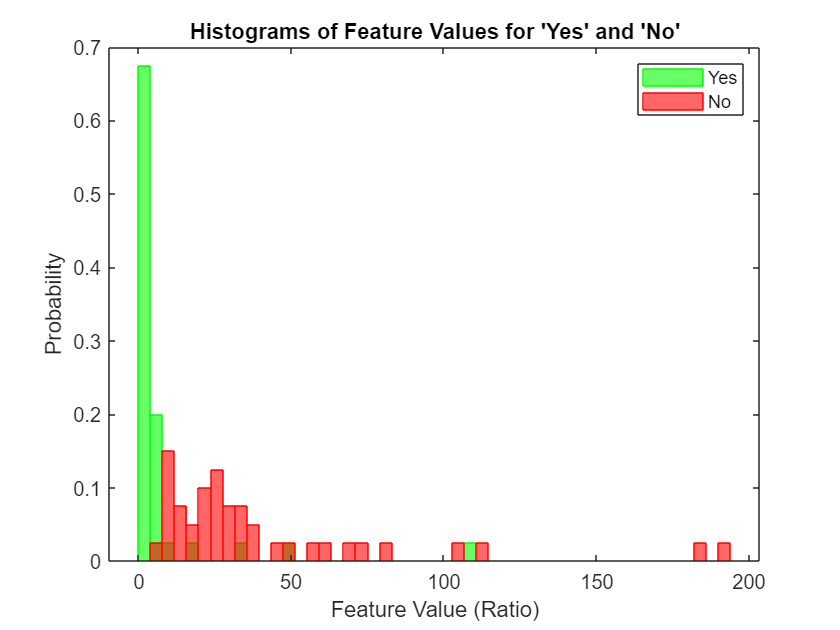

% Initialize vectors to store feature values
yes_ratios = zeros(1, length(allYesSignals));
no_ratios = zeros(1, length(allnoSignals));

% Define frequency ranges for FOI and FONI based on your observations
% Example frequency range for FOI (Frequency of Interest)
freq_low_foi = 4101;   % Adjust based on the characteristics of your signals
freq_high_foi = 8000;  % Adjust based on the characteristics of your signals
foi_range = [freq_low_foi, freq_high_foi];

% Example frequency range for FONI (Frequency of No Interest)
freq_low_foni = 0;   % Adjust based on the characteristics of your signals
freq_high_foni = 4100; % Adjust based on the characteristics of your signals
foni_range = [freq_low_foni, freq_high_foni];

% Calculate feature for 'yes' files
for i = 1:length(allYesSignals)
    ratio = calculateRatio(allYesSignals{i}, fs, foi_range, foni_range);
    yes_ratios(i) = ratio;
end

% Calculate feature for 'no' files
for i = 1:length(allnoSignals)
    ratio = calculateRatio(allnoSignals{i}, fs, foi_range, foni_range);
    no_ratios(i) = ratio;
end

% Create histograms
figure;
histogram(yes_ratios, 'BinEdges', linspace(0, max([yes_ratios, no_ratios]), 50), 'Normalization', 'probability', 'FaceColor', 'g', 'EdgeColor', 'g');
hold on;
histogram(no_ratios, 'BinEdges', linspace(0, max([yes_ratios, no_ratios]), 50), 'Normalization', 'probability', 'FaceColor', 'r', 'EdgeColor', 'r');
xlabel('Feature Value (Ratio)');
ylabel('Probability');
title('Histograms of Feature Values for ''Yes'' and ''No''');
legend('Yes', 'No');
hold off;

% Manually inspect the histograms and decide a suitable threshold
threshold = 5;

audioFile1 = 'Speech soundfiles\yes\0a7c2a8d_nohash_0.wav';
classification1 = classifyAudio(audioFile1, threshold, freq_low_foi, freq_high_foi, freq_low_foni, freq_high_foni);
disp(['File 1 is classified as: ', classification1]);

File 1 is classified as: Yes


audioFile2 = 'Speech soundfiles\no\01bb6a2a_nohash_1.wav';
classification2 = classifyAudio(audioFile2, threshold, freq_low_foi, freq_high_foi, freq_low_foni, freq_high_foni);
disp(['File 2 is classified as: ', classification2]);

File 2 is classified as: No


(d) Use the provided function YESNOFeature.m in order to test your recognition of ’yes’ and ’no’ with your own recorded voice. 

classifyRec(44100, threshold, freq_low_foi, freq_high_foi, freq_high_foni, freq_high_foni)

Start speaking.
End of Recording.


ans = 'Yes'